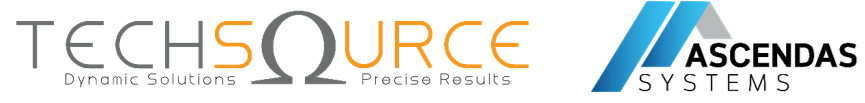

# Hands-On Workshop — Stateflow, Code Generation & Deployment ke Arduino Uno

## Model Battery State Controller (ID)

**Metadata ·**

- **Durasi** — 120 menit (40 menit instruksi + 50 menit praktik + 30 menit deploy & tantangan)

- **Produk MATLAB** — MATLAB, Simulink, Stateflow, Embedded Coder, Simulink Support Package for Arduino Hardware

- **Hardware Target** — Arduino Uno (ATmega328P) — 1 board per kelompok (3 orang)

- **Prasyarat** — Dasar MATLAB (variabel, script) dan dasar Simulink (blok, simulasi)

## 1. Ringkasan Workshop

Dalam workshop 2 jam ini, Anda akan membangun **Battery State Controller** — sebuah mesin keadaan (finite-state machine) yang memantau tegangan, arus, dan suhu baterai lalu menentukan mode operasinya:

**State · Arti · LED (state_id)**

- **IDLE** — Tegangan aman, arus mendekati nol · D8 ON (0)

- **CHARGING** — Tegangan aman, arus positif · D9 ON (1)

- **DISCHARGING** — Tegangan aman, arus negatif · D10 ON (2)

- **FAULT** — Undervoltage / overvoltage / overtemperature · D8, D9, D10 ON (3)

Anda mulai dari **starter model** (`starter_model.slx`) yang sudah berisi rangka simulasi, lalu:

- ✅ **Verifikasi toolbox** — pastikan Stateflow, Embedded Coder, dan support package Arduino terpasang.

- ✅ **Bangun chart Stateflow** — tambahkan 4 state, transisi, dan aksi `during` dari requirement.

- ✅ **Simulasi & validasi** — jalankan 7 test case dari `tests/battery_mode_test_cases.csv`.

- ✅ **Generate kode** — hasilkan kode C dengan Embedded Coder.

- ✅ **Deploy ke Arduino Uno** — flash board dan baca paket status serial.

- ✅ **Tantangan** — ubah threshold undervoltage 9.0 V → 9.6 V lalu deploy ulang.

💡 **Model completed** (`models/completed_model.slx`) adalah kunci jawaban Anda. Gunakan jika ketinggalan — tapi coba bangun sendiri dulu.

## 2. Tujuan Pembelajaran

Setelah sesi ini Anda dapat:

- ✅ Memverifikasi toolbox MathWorks dan support package hardware yang diperlukan.

- ✅ Membuka dan menavigasi chart Stateflow di dalam Simulink.

- ✅ Memodelkan mesin keadaan dengan **state, transisi, dan guard** (`[kondisi]`).

- ✅ Menggunakan aksi `during` untuk menggerakkan output setiap step.

- ✅ Menghubungkan Stateflow ke input/output Simulink (data scope: Input/Output).

- ✅ Mensimulasikan model dan memvalidasi perilaku terhadap requirement.

- ✅ Men-generate kode C embedded dan memahami file yang dihasilkan.

- ✅ Mendeploy model Simulink ke **Arduino Uno** dan membaca output serial.

## 3. Verifikasi Toolbox (Langkah 0, ~10 menit)

Buka MATLAB dan jalankan **project file** lebih dulu agar path dan pengaturan sudah terkonfigurasi:

>> openProject('StateflowCodeGenerationWorkshop.prj')


Lalu verifikasi setiap produk yang diperlukan:

>> ver('stateflow')      % Stateflow
>> ver('simulink')       % Simulink
>> ver('ecoder')         % Embedded Coder


🪟 **Jalankan di MATLAB Command Window (satu window).** Tabel versi muncul berarti produk terpasang. Jika ada produk **hilang**, pasang dari **Home → Add-Ons → Get Add-Ons** (cari nama produk).

**Pastikan juga support package Arduino** (ini *Support Package*, bukan Toolbox, sehingga tidak muncul di `ver`):

>> supportPackageInstaller


Di jendela installer, pastikan **"Simulink Support Package for Arduino Hardware"** berstatus **Installed**. Jika belum, pilih dan klik **Install**.

**Produk minimal yang diharapkan (dari **`ver`**):**

**Product · argumen ver · Fungsi**

- **Stateflow** — `ver('stateflow')` · Pemodelan state machine

- **Simulink** — `ver('simulink')` · Host model

- **Embedded Coder** — `ver('ecoder')` · Kode C optimal siap hardware

🔧 **Menginstal produk yang hilang (toolbox):** buka **Home → Add-Ons → Get Add-Ons** (Add-On Explorer), cari nama produk, lalu klik **Install** (butuh koneksi internet + akun MathWorks). **Dependency Analyzer** (App → atau `analyze` pada model/dependency-nya) mengonfirmasi produk yang dibutuhkan untuk workshop ini: **MATLAB, Simulink, Stateflow, Embedded Coder** — plus **Simulink Support Package for Arduino Hardware** untuk deployment.

## 4. Buka Starter Model (Langkah 1, ~5 menit)

>> open_system('models/starter_model.slx')


Starter model sudah berisi (read-only untuk langkah ini):

- **Dashboard Knobs** — `Voltage_Knob_V`, `Current_Knob_A`, `Temperature_Knob_C` (input simulasi).

- **Source Select** — `Voltage_Source_Select`, `Current_Source_Select`, `Temperature_Source_Select` (saklar antara knob simulasi dan pin Arduino nyata).

- **Input Scaling** — mengonversi knob/ADC menjadi `Vpack`, `Ipack`, `BatteryTemp_C`.

- **Battery State Controller** — chart Stateflow. Pada starter ini **kosong** (belum ada state).

- **LED Output** — menggerakkan `led_idle`, `led_charging`, `led_discharging`, `state_id`.

- **Blok Serial** — `Serial_Packet_Mux` + `Arduino_Serial_Transmit` (aktif hanya di hardware).

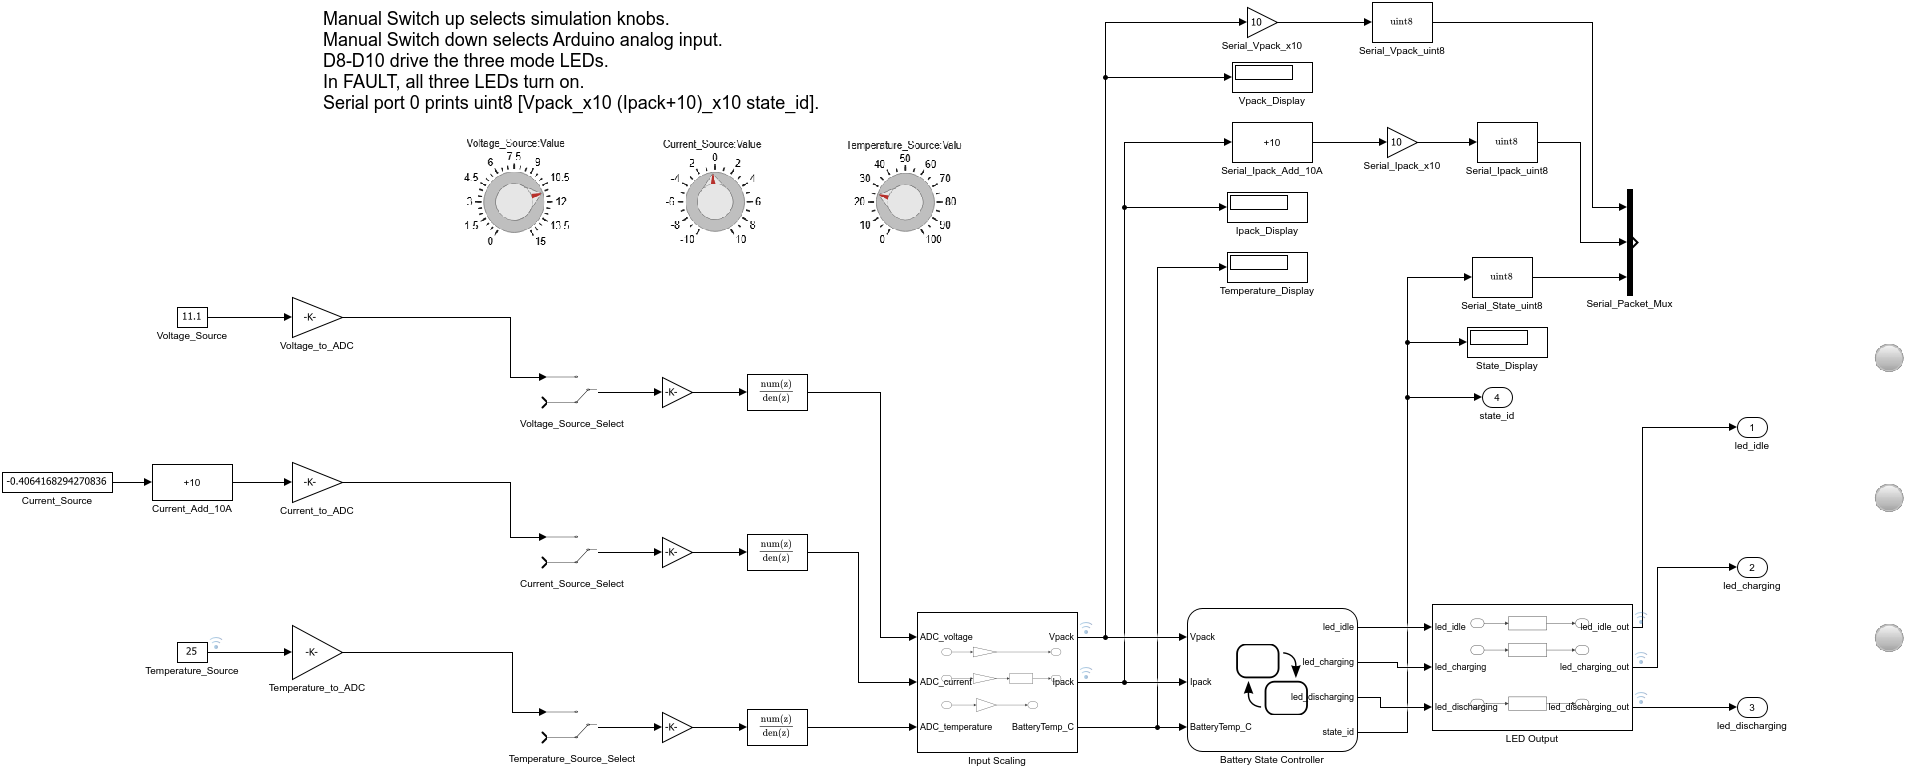

*Gambar 1: Model top-level saat dibuka pada starter — perhatikan blok ****Battery State Controller**** masih kosong. Input simulasi (Dashboard Knobs) masuk ke Input Scaling, chart akan menentukan state, dan LED + Serial melaporkannya.*

🎤 **Narasi (presenter):** "Starter model ini seperti mobil tanpa mesin. Seluruh kabel — dashboard, scaling, panel LED — sudah terhubung. Tugas Anda di langkah berikutnya adalah memasang *otak*-nya: chart Stateflow yang membaca Vpack, Ipack, dan BatteryTemp_C lalu memutuskan state kita berada di mana."

## 5. Bangun Chart Stateflow (Langkah 2–6, ~40 menit)

Klik dua kali chart **Battery State Controller** untuk membuka Stateflow Editor.

### Langkah 2: Tambahkan empat state

Seret **empat bentuk State** dari palet Stateflow (atau klik kanan → **Add State**) ke kanvas. Klik dua kali masing-masing dan beri nama:

**Nama state · Posisi (saran)**

- **IDLE** — kiri, atas

- **CHARGING** — tengah, atas

- **DISCHARGING** — kiri, bawah

- **FAULT** — tengah, bawah

### Langkah 3: Tambahkan aksi `during` pada tiap state

Klik di dalam tiap state dan ketik aksi `during`-nya (berjalan setiap step simulasi saat state aktif):

% IDLE
during:
 led_idle = true;  led_charging = false; led_discharging = false; state_id = uint8(0);


% CHARGING
during:
 led_idle = false; led_charging = true;  led_discharging = false; state_id = uint8(1);


% DISCHARGING
during:
 led_idle = false; led_charging = false; led_discharging = true;  state_id = uint8(2);


% FAULT
during:
 led_idle = true;  led_charging = true;  led_discharging = true;  state_id = uint8(3);


💡 **Mengapa **`during`**?** Chart dievaluasi ulang setiap step. Aksi `during` menjaga LED dan `state_id` tetap benar selama state aktif — persis seperti yang diminta requirement (REQ-06, REQ-07).

### Langkah 4: Tambahkan transisi (guard)

Tarik **transisi** dari satu state ke state lain, lalu klik dua kali panah dan ketik kondisi guard di dalam `[ ]`. Buat semua transisi dari `requirements/battery_mode_requirements.csv`:

**Dari → Ke · Kondisi guard · Requirement**

- **IDLE → CHARGING** — `[Ipack > 1.0 && Vpack >= 9.0 && Vpack <= 12.6]` · REQ-04

- **IDLE → DISCHARGING** — `[Ipack < -1.0 && Vpack >= 9.0 && Vpack <= 12.6]` · REQ-05

- **IDLE → FAULT** — `[Vpack < 9.0 · Vpack > 12.6 · BatteryTemp_C > 50]` · REQ-01/02/08

- **CHARGING → IDLE** — `[Ipack <= 1.0 && Ipack >= -1.0]` · REQ-03

- **CHARGING → DISCHARGING** — `[Ipack < -1.0 && Vpack >= 9.0 && Vpack <= 12.6]` · REQ-05

- **CHARGING → FAULT** — `[Vpack < 9.0 · Vpack > 12.6 · BatteryTemp_C > 50]` · REQ-01/02/08

- **DISCHARGING → IDLE** — `[Ipack <= 1.0 && Ipack >= -1.0]` · REQ-03

- **DISCHARGING → CHARGING** — `[Ipack > 1.0 && Vpack >= 9.0 && Vpack <= 12.6]` · REQ-04

- **DISCHARGING → FAULT** — `[Vpack < 9.0 · Vpack > 12.6 · BatteryTemp_C > 50]` · REQ-01/02/08

- **FAULT → IDLE** — `[Vpack >= 9.0 && Vpack <= 12.6 && BatteryTemp_C <= 50 && Ipack >= -1.0 && Ipack <= 1.0]` · recovery

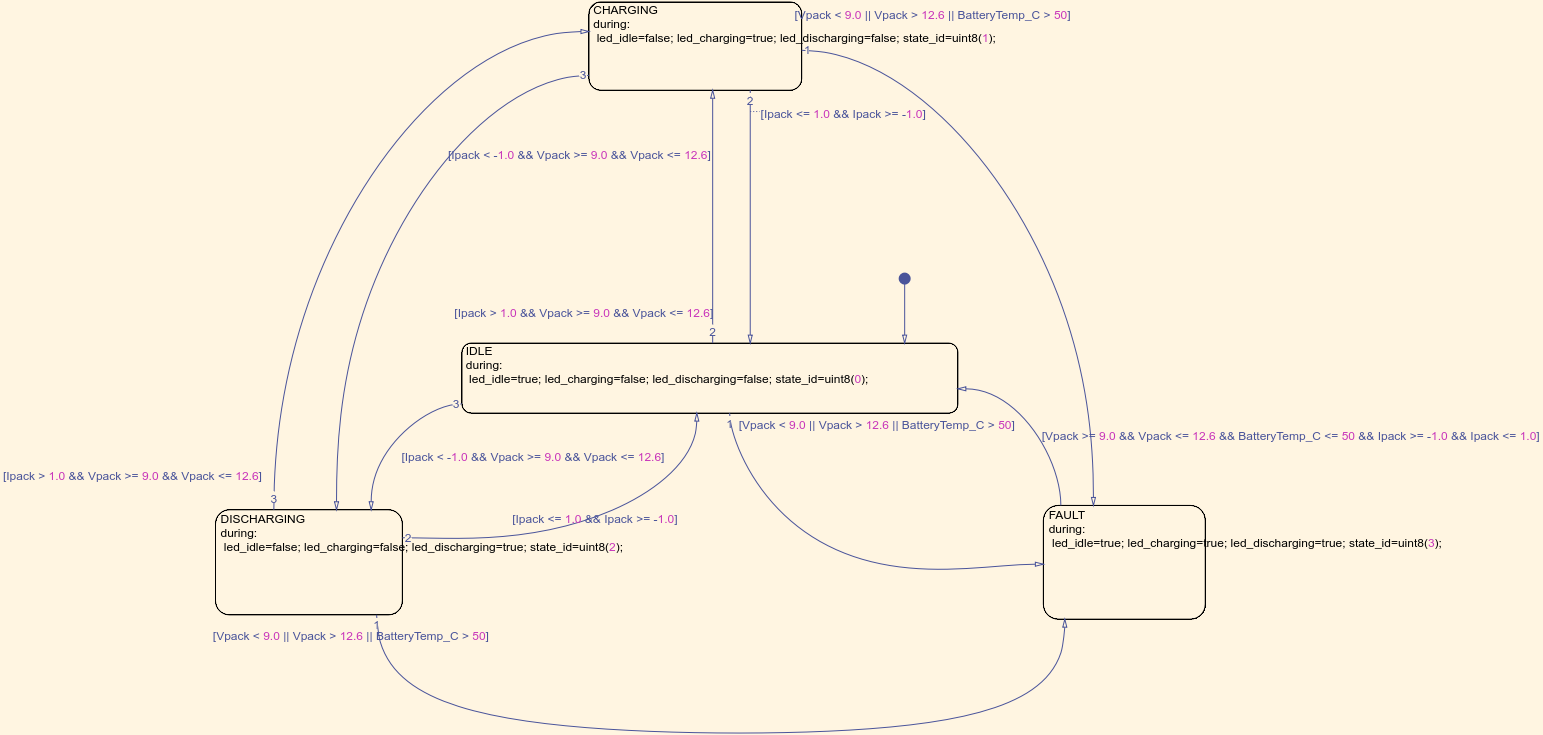

*Gambar 2: Chart 4-state lengkap dengan semua transisi, seperti tampak di Stateflow Editor. Gunakan ini sebagai referensi saat menggambar.*

### Langkah 5: Pastikan data chart (input / output)

Di Stateflow Editor, buka pane **Symbols** (atau **Model Explorer**). Chart harus mengekspos:

**Simbol · Scope · Tipe**

- **Vpack** — Input · double

- **Ipack** — Input · double

- **BatteryTemp_C** — Input · double

- **led_idle** — Output · boolean

- **led_charging** — Output · boolean

- **led_discharging** — Output · boolean

- **state_id** — Output · uint8

✅ Jika Anda menamai state dan aksi persis seperti di atas, Stateflow otomatis menyelesaikan simbol ini. Jika ada simbol berwarna merah **?**, klik kanan → **Resolve to Input/Output Data**.

### Langkah 6: Update & simpan

>> set_param('starter_model','SimulationCommand','update')
>> save_system('starter_model')


## 6. Simulasi & Validasi (Langkah 7, ~15 menit)

Untuk simulasi desktop, biarkan switch **Source Select** posisi **atas** (menuju Dashboard knob).

### Langkah 7a: Jalankan 7 test case

Buka `tests/battery_mode_test_cases.csv`. Untuk tiap baris, atur ketiga knob ke nilai `Vpack`, `Ipack`, `Temperature_C`, lalu **Run** (Ctrl+T) dan baca `state_id` / State Display.

**# · Test Case · Vpack · Ipack · Temp (°C) · Expected State · state_id**

- **1** — Normal idle · 11.1 · 0 · 25 · IDLE · 0

- **2** — Charging · 11.1 · 5 · 25 · CHARGING · 1

- **3** — Discharging · 11.1 · -5 · 25 · DISCHARGING · 2

- **4** — Undervoltage fault · 8.5 · 0 · 25 · FAULT · 3

- **5** — Overvoltage fault · 13.0 · 0 · 25 · FAULT · 3

- **6** — Overtemperature fault · 11.1 · 0 · 60 · FAULT · 3

- **7** — Fault recovery · 11.1 · 0 · 25 · IDLE · 0

✅ **Kriteria lulus:** blok State Display menunjukkan Expected State dan `state_id` cocok untuk ke-7 kasus. Jika gagal, periksa ulang kondisi guard (Langkah 4) — salah ketik `&&` / `||` adalah penyebab umum.

🪟 **Tips:** seret knob, lalu klik **Run**. Amati `Vpack_Display`, `Ipack_Display`, `State_Display`. Nilai yang diharapkan muncul setelah satu sample step (SampleTime 0.1 s).

## 7. Generate Kode (Langkah 8, ~10 menit)

Setelah logika tervalidasi, hasilkan kode C embedded:

>> slbuild('starter_model')


Perintah ini menjalankan **Embedded Coder** menggunakan konfigurasi model:

- System target file: `ert.tlc`

- Hardware board: **Arduino Uno**

- Toolchain: **Arduino AVR**

**Periksa kode yang dihasilkan** (ada di `starter_model_ert_rtw/`):

**File · Isinya**

- **starter_model.c / .h** — Entry point model (`model_initialize`, `model_step`, `model_terminate`)

- **starter_model_data.c** — Parameter dan data sinyal

- **ert_main.c** — Contoh main loop (tidak dipakai di Arduino — support package menyediakan miliknya)

- **starter_model_generate_report.html** — Laporan code generation

💡 **Poin utama:** chart Stateflow yang Anda gambar menghasilkan fungsi `model_step()` yang mengalihkan state dalam C biasa — tanpa coding manual. Buka `starter_model.c` dan cari `IDLE` / `CHARGING` untuk melihat bagaimana Stateflow mengompilasi state menjadi `switch` pada variabel state.

⚠️ Lisensi **Embedded Coder** diperlukan untuk `slbuild`. Jika hanya punya Arduino Support Package, langkah *deploy* (Langkah 9) tetap berjalan karena memicu generate kode secara internal — tapi laporan `slbuild` adalah cara paling jelas untuk *melihat* kodenya.

## 8. Deploy ke Arduino Uno (Langkah 9, ~15 menit)

### Langkah 9a: Alihkan ke input hardware

Di model, setel ketiga switch **Source Select** posisi **bawah** (menuju pin Arduino):

- `Voltage_Source_Select` → Arduino **A0** (pembagi tegangan baterai)

- `Current_Source_Select` → Arduino **A1** (sensor arus)

- `Temperature_Source_Select` → Arduino **A2** (suhu)

Blok LED Output sudah memetakan ke pin digital:

**State · Pin · LED**

- **IDLE** — D8 · led_idle

- **CHARGING** — D9 · led_charging

- **DISCHARGING** — D10 · led_discharging

- **FAULT** — D8, D9, D10 · led_idle + led_charging + led_discharging (semua ON)

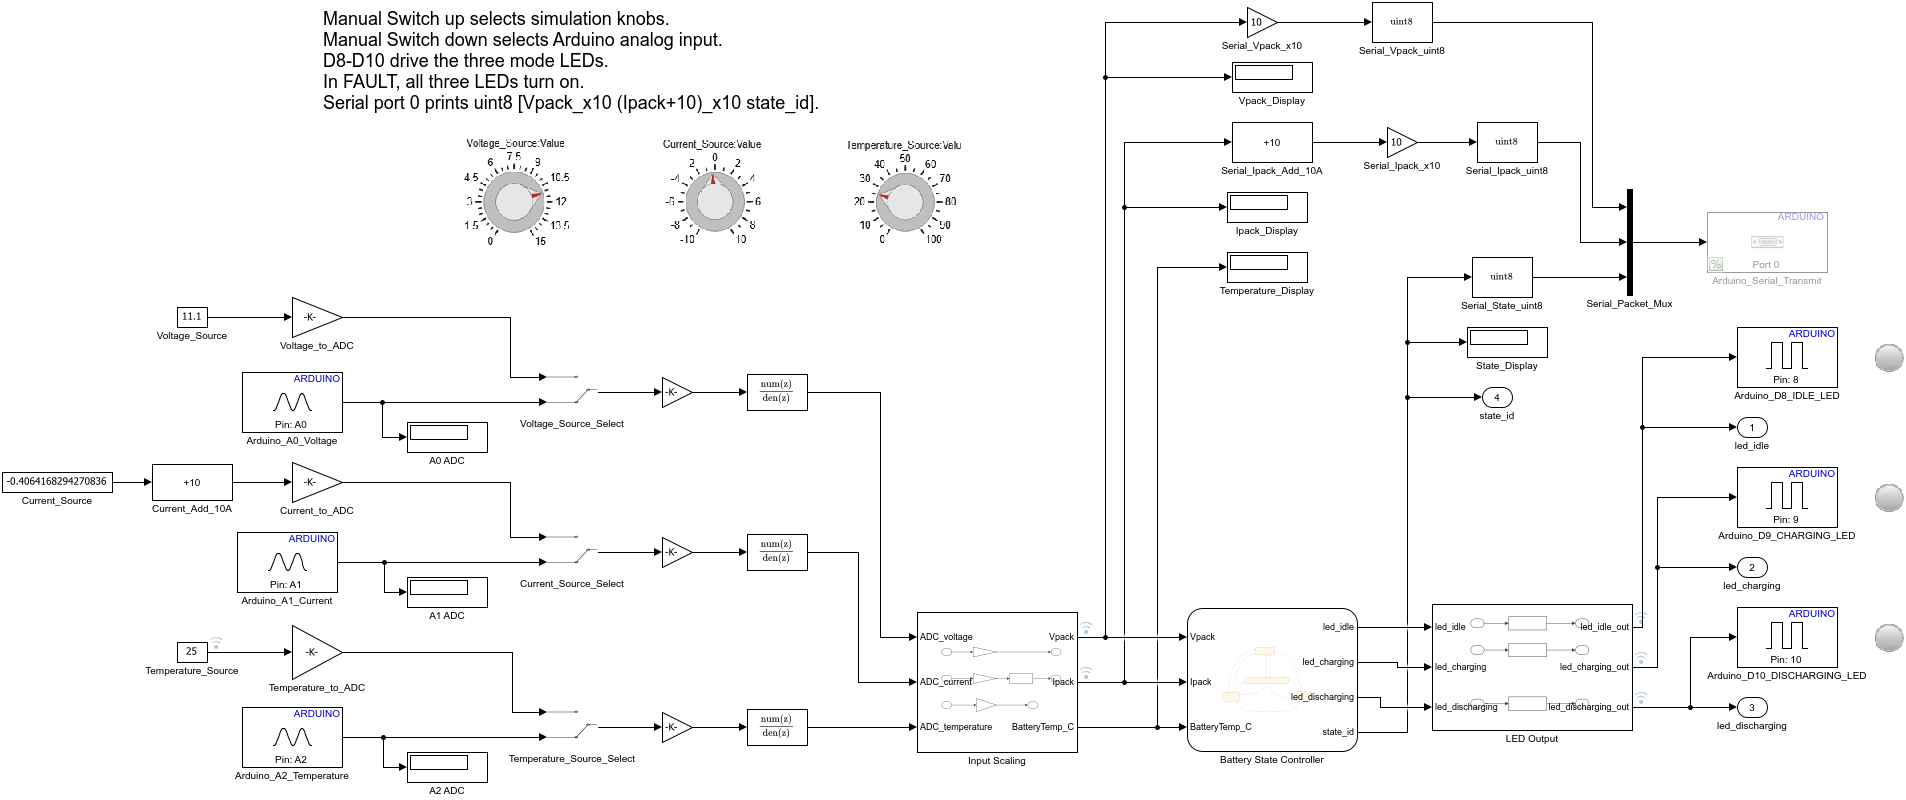

*Gambar 3: Model top-level lengkap siap di-deploy — switch Source Select menuju pin Arduino (A0/A1/A2), dengan blok LED Output dan Serial sudah terhubung.*

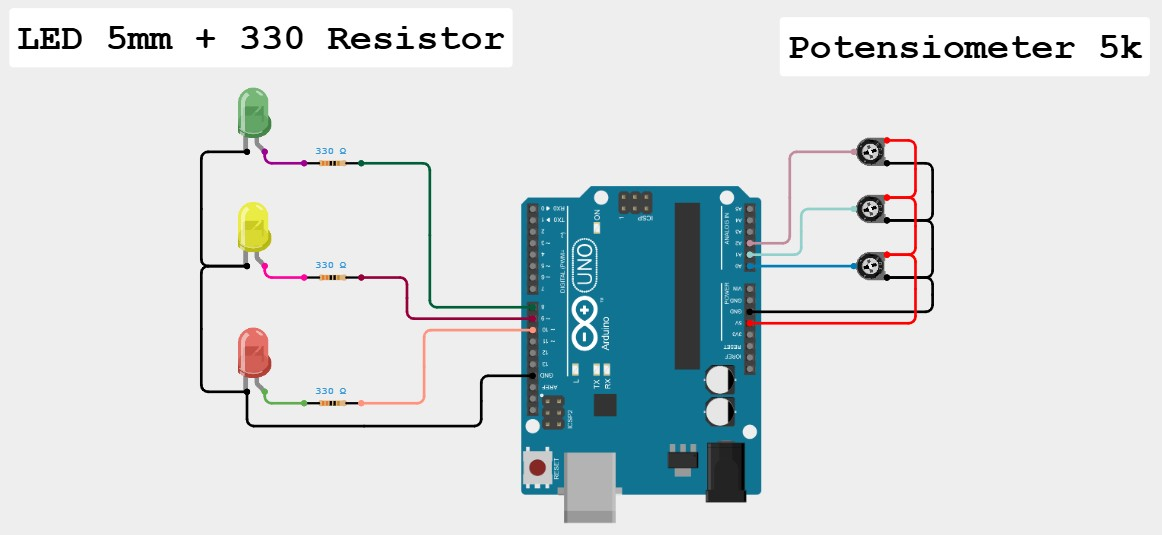

*Gambar 4: Seluruh hardware yang sudah dirakit — potensiometer di A0/A1/A2 dan tiga LED status (330 Ω) di D8/D9/D10.*

🛠️ **Wiring (per kelompok):** hubungkan potensiometer **1 kΩ–20 kΩ** ke A0 (simulasikan Vpack), A1 (Ipack), A2 (suhu). Hubungkan **3 LED** dengan resistor 330 Ω ke **D8, D9, D10** (GND). Untuk cek cepat, putar A0: tegangan rendah → FAULT (D8, D9, D10 semua menyala), aman di tengah → IDLE (hanya D8), naikkan A1 di atas tengah → CHARGING (hanya D9), turunkan A1 di bawah tengah → DISCHARGING (hanya D10).

### Langkah 9b: Konfigurasi & build untuk hardware

- **Apps → Hardware Setup** atau atur di **Model Settings (Ctrl+E)**:

- **Hardware Implementation → Hardware board:** `Arduino Uno`

- **Solver:** `Fixed-step`, `discrete (no continuous states)`, Fixed-step size `0.1`

- **Hardware → Build, Deploy & Start** (atau `Ctrl+B`).

MATLAB mengompilasi, mengunggah `.hex` ke Uno lewat USB, dan menjalankannya.

### Langkah 9c: Baca paket status serial

Buka **Arduino Serial Monitor** (atau MATLAB `serialport`) pada baud default. Model mengirim satu paket byte tiap step:

[ Vpack_x10 , (Ipack+10)_x10 , state_id ]


Contoh: `111 100 0` → Vpack = 11.1 V, Ipack = 0.0 A, state = **IDLE**.

% Opsional: baca dari MATLAB, bukan Serial Monitor
>> s = serialport("COM3", 9600);   % ganti COM3 dengan port Anda
>> read(s, 3, "uint8")


💡 Hanya satu host yang boleh membuka port serial sekaligus — tutup Arduino Serial Monitor sebelum pakai `serialport` di MATLAB, dan sebaliknya.

## 9. Tantangan (Langkah 10, ~10 menit)

Ubah **threshold undervoltage** dari `9.0` menjadi `9.6` V pada setiap guard yang mencantumkannya:

- IDLE → FAULT, CHARGING → FAULT, DISCHARGING → FAULT: `[Vpack < 9.6 || Vpack > 12.6 || BatteryTemp_C > 50]`

- IDLE → CHARGING / DISCHARGING, dan guard recovery/charging: gunakan `Vpack >= 9.6` pada rentang aman.

Jalankan ulang test case 4 dengan `Vpack = 9.3`: sebelumnya **IDLE** (9.3 ≥ 9.0 = aman), kini menjadi **FAULT** — guard baru `[Vpack < 9.6 …]` memicu, sehingga LED fault menyala pada tegangan lebih tinggi dari sebelumnya. Deploy ulang ke Arduino jika waktu memadai.

🔴 **Ekstensi lanjut:** tambahkan state ke-5 `BALANCING` dan rentang histeresis agar controller tidak "chatting" antara CHARGING dan DISCHARGING saat Ipack berada dekat 0 A.

## 10. Ringkasan

**Fase · Perintah / Aksi · Poin Utama**

- **Verifikasi** — `ver('stateflow')`, `supportPackageInstaller` · Tahu apa yang terpasang sebelum membangun

- **Model** — Chart Stateflow: state + `[guard]` + `during` · State machine hanyalah state + transisi berguard

- **Simulasi** — Dashboard knob + 7 test case · Validasi logika *sebelum* menyentuh hardware

- **Generate** — `slbuild('starter_model')` · Stateflow → kode C embedded yang readable

- **Deploy** — Hardware board = Arduino Uno, `Ctrl+B` · Model yang sama berjalan di silikon nyata

- **Amati** — Paket serial `[V I state]` · Loop tertutup: model ↔ hardware

### Arsitektur yang Dipelajari

Requirements (CSV)  ->  Chart Stateflow  ->  Model Simulink  ->  Kode C Generated  ->  Arduino Uno
        REQ-01..08        4 state              LED+Serial         ert.tlc          D8, D9, D10 + Serial


## 11. Troubleshooting

**Masalah · Kemungkinan Penyebab · Solusi**

- **Arduino support package hilang** — Belum terpasang · `supportPackageInstaller` → instal "Simulink Support Package for Arduino Hardware"

- **Simbol merah ? di chart** — Scope belum resolve · Klik kanan simbol → Resolve ke Input/Output Data

- **Salah state di simulasi** — Typo di guard `&&` / ` · ` · Bandingkan guard dengan tabel Langkah 4 baris per baris

- **Error lisensi slbuild** — Tidak ada lisensi coder · Gunakan Deploy (`Ctrl+B`) yang generate internal; atau dapatkan Embedded Coder

- **Upload gagal / "port busy"** — Serial Monitor terbuka atau COM salah · Tutup Serial Monitor; pilih COM benar di Device Manager

- **LED tak pernah menyala di Uno** — Source Select masih "atas" · Balik ketiga switch Source Select ke **bawah** (pin Arduino)

- **state_id salah di hardware** — Knob masih menggerakkan input · Pastikan Source Select = bawah (Arduino A0/A1/A2)

## 12. Referensi MathWorks

- Getting Started with Stateflow (https://www.mathworks.com/help/stateflow/getting-started-with-stateflow.html)

- Model Finite State Machines (https://www.mathworks.com/help/stateflow/ug/why-use-stateflow-charts.html)

- Generate Code for Arduino Hardware (Simulink) (https://www.mathworks.com/help/supportpkg/arduino/ug/install-support-for-arduino-hardware.html)

- Simulink Support Package for Arduino Hardware (https://www.mathworks.com/hardware-support/arduino-simulink.html)

- Getting Started with Embedded Coder (https://www.mathworks.com/help/ecoder/getting-started-with-embedded-coder.html)

*Materi Workshop Hands-On · TechSource Systems*